## L4, L5: Filtracja sygnału audio

Autorzy: Tomasz Pawlak, Maciej Łodziński

Na przedstawionym nagraniu, oprócz rozmowy dwóch osób, pojawiają się dwa rodzaje zakłóceń. Pierwszym jest stały przydźwięk spowodowany sprzężeniem sieciowym. Drugie zakłócenie pojawia się pod koniec nagrania - jest to sygnał budzika. Proszę przefiltrować nagranie w taki sposób, aby oba te zakłócenia usunąć, pozostawiając przy tym możliwie najmniejsze zniekształcenia właściwej mowy.

W ramach zadania proszę przygotować zestaw filtrów typu windowed-sinc, które będą wycinały odpowiednie pasma częstotliwości. Analizę pasm do wycięcia proszę wykonać "naocznie" na podstawie analizy spektrogramu nagrania. Filtry powinny być wyznaczane zgodnie z metodami przestawionymi na wykładzie:

- filtr dolnoprzepustowy liczony z definicji, dla podanej stromości zbocza *BW* i częstotliwości odcięcia *f**c* powinien produkować odpowiedniej długości jądro przekształcenia,

- filtr górnoprzepustowy powinien powstawać przez inwersję (bądź rewersję) spektralną filtra dolnoprzepustowego,

- filtry pasmowoprzepustowy i pasmowoblokujący powinny być tworzone przez odpowiednią kombinację filtrów dolno- i górnoprzepustowego. 

W ramach rozwiązania proszę przygotować **co najmniej** **dwa różne filtry: ****filtr dolnoprzepustowy oraz pasmowoblokujący.**

Filtracji sygnału proszę dokonać przez wykorzystanie standardowej funkcji splotu (**conv**). Proszę pamiętać o tym, że parametry filtrów wyznaczane są w relacji do częstotliwości próbkowania, a więc częstotliwości wyrażone w *Hz* należy odpowiednio przeliczać na ułamek [0 - 0.5]. Zalecany nagłówek funkcji wyznaczającej filtr dolnoprzepustowy (pozostałe analogicznie):

**function F = lowpass(fc, bw, fs)**

Jako rozwiązanie należy przedstawić sprawozdanie (PDF) zawierające:

- spektrogram sygnału wejściowego,

- analizę zakresów częstotliwości do wycięcia,

- charakterystykę amplitudową przygotowanych filtrów (wzmocnienie w dziedzinie częstotliwości),

- spektrogram sygnału po zastosowaniu filtrów,

- komentarz dotyczący jakości otrzymanego nagrania (tzn. nauszne stwierdzenie, jak duże zniekształcenia sygnału użytecznego spowodowała filtracja),

- kody funkcji dokonujących wszystkich obliczeń (wyznaczanie filtrów oraz ich aplikacja do sygnału).

## Załadowanie pliku

- czytanie częstotliwości pliku oraz kolejnych klatek

[x, fs] = audioread('noised.wav');
    
    win_len = 512;   % wielkość okna do analizy
    win_overlap = win_len/2; % nakładanie ramek
    nfft = win_len; % liczba próbek do FFT
    bw = 100;   % współczynnik filtra

## Analiza widma spektralnego sygnału

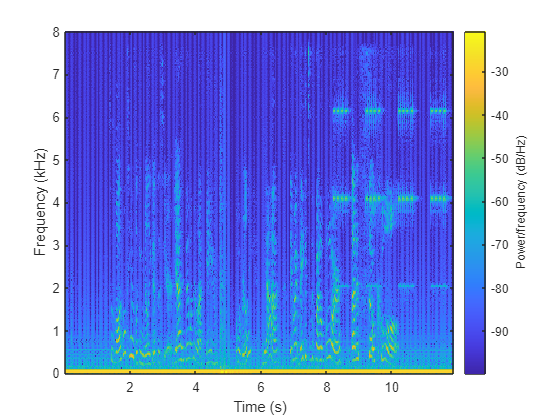

    spectrogram(x, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis');

Należy odciąć freq (<150 Hz , 1.95-2.15kHz , 4-4.2kHz , 6.05-6.25kHz)

Aby zastosować filtr górnoprzepustowy jako dolnoprzepustowy należy od sygnału bez filtra odjąć ten z górnoprzepustowym.

Cel zadania:

- zastosować dolnoprzepustowy do odcięcia 50Hz 

- zastosować 3 pasmowoblokujące do odcięcia 3 składowych budzika

## Implementacja Filtra Dolnoprzepustowego

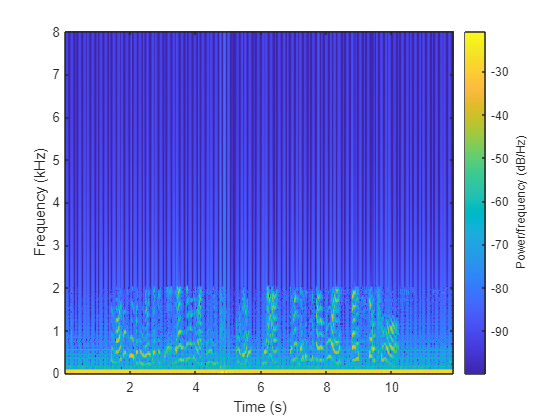

F1 = lowpass_filter(2000, bw, fs);
sf1 = conv(x, F1, 'same');
spectrogram(sf1, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis');

## Implementacja Filtra Górnoprzepustowego

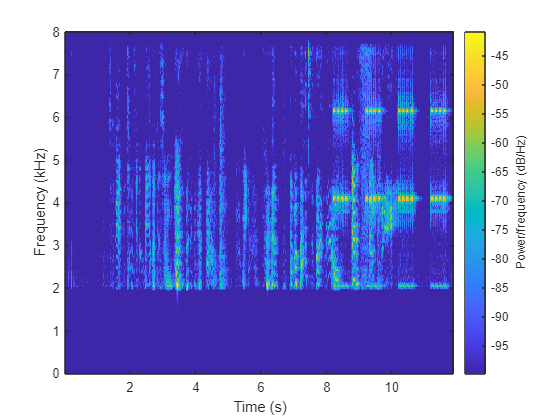

F2 = highpass_filter(2000, 100, fs);
sf2 = conv(x, F2, 'same');
spectrogram(sf2, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis');

## Implementacja filtra środkowo-przepustowego

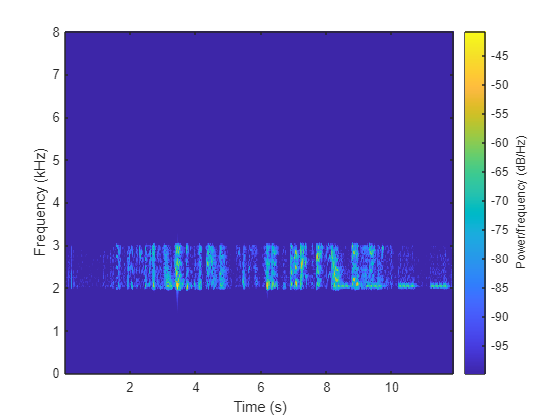

F3 = middlepass_filter(2000, 3000, bw, fs);
sf3 = conv(x, F3, 'same');
spectrogram(sf3, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis');

## Implementacja filtra środkowo-zaporowego

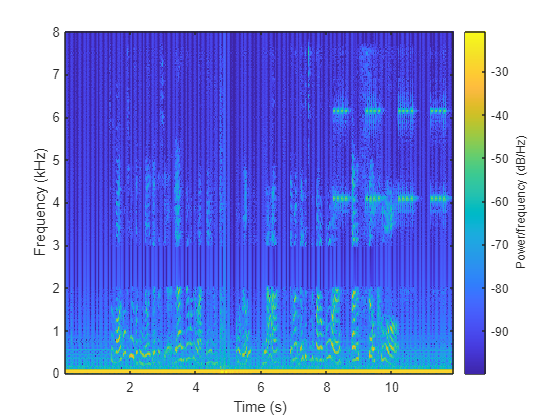

F4 = middlestop_filter(2000, 3000, bw, fs);
sf4 = conv(x, F4, 'same');
spectrogram(sf4, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis');

## Odcięcie przeszkadzających częstotliwości

- Należy odciąć freq (<150 Hz , 1.95-2.15kHz , 4-4.2kHz , 6.05-6.25kHz)

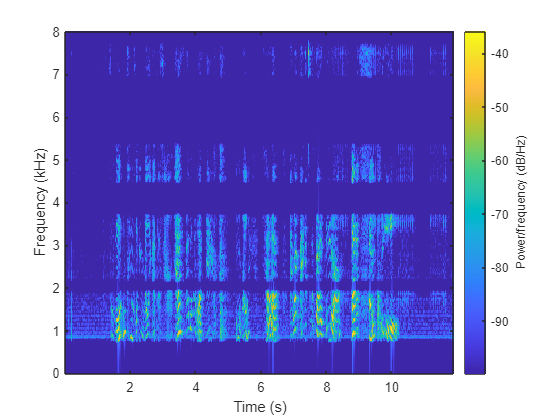

filter1 = highpass_filter(800, bw, fs);
sf = conv(x, filter1, 'same');
mid2 = 2050;
rad2 = 150;
filter2 = bandstop_filter(mid2-rad2, mid2+rad2, bw, fs);
sf = conv(sf, filter2, 'same');
mid3 = 4100;
rad3 = 400;
filter3 = bandstop_filter(mid3-rad3, mid3+rad3, bw, fs);
sf = conv(sf, filter3, 'same');
mid4 = 6150;
rad4 = 800;
filter4 = bandstop_filter(mid4-rad4, mid4+rad4, bw, fs);
sf = conv(sf, filter4, 'same');
spectrogram(sf, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis');

## Wygenerowanie dźwięku do pliku audio

audiowrite('unnoised.wav', sf, fs);
audiowrite('noise.wav', x-sf, fs);

## Komentarz dotyczący jakości otrzymanego nagrania

- Dźwięk jest odszumiony z częstotliowści 50Hz, ta częstotliwość jest prawie niesłyszalna.

- Dźwięki budzika, na których wykonaliśmy 3 pasma zaporowe zostały wyciszone w gorszy sposób, ponieważ budzik nie składa się z 3 wąskich pasm, ale również z pogłosów, których wycięcie byłoby możliwe jedynie wraz z wycięciem głosu z nagrania czego byśmy nie chcieli.

- Głos na nagraniu jest lekko przytłumiony, co jest następstwem nachodzenia się pasm głosu i dźwięków do wytłumienia. Zniekształcenie jest znaczące lecz nie przeszkadza w rozumieniu mowy.

- Nagranie szumu rzeczywiście składa się z szumów wyciętych z nagrania

## Funkcje generujące filtry użyte w zadaniu

function filter = lowpass_filter(fc, bw, fs)
    % fc - freq odcięcia (Hz)
    % (M+1) - dł maski (nieparzysta l. elementów)
    % M ~~ 4/BW M = 4/100/fs
    % K jest obliczone jako 1/sum(filter)

    fc = fc/fs;     % wprowadzamy freq do funkcji jako wartosc a nie fraq.
    M = round(fs*4/bw);
    filter = zeros(M+1,1);  % inicjacja maski filtra
    for i=0:M   % nieparzysta długość maski, Okno Blackmana
        filter(i+1) = sin(2*pi*fc*(i-M/2))/(i-M/2)*(0.42-0.5*cos(2*pi*(i)/M)+0.08*cos(4*pi*(i)/M));
    end
    filter(M/2+1) = 2*pi*fc;
    K=1/sum(filter);
    filter = K*filter;
end

function filter = highpass_filter(fc, bw, fs)
    filter = lowpass_filter(fc, bw, fs);
    for i=1:1:size(filter,1)
        filter(i) = -1*filter(i);
    end
    filter((size(filter,1)+1)/2) = filter((size(filter,1)+1)/2) + 1;
end

function filter = bandpass_filter(fc0, fc1, bw, fs)
    if fc0>fc1
        filter = -1;
        return
    end
    high_filter = highpass_filter(fc0, bw, fs);
    low_filter = lowpass_filter(fc1, bw, fs);
    filter = conv(low_filter,high_filter); % splot dwóch filtrów
end

function filter = bandstop_filter(fc0, fc1, bw, fs)
    if fc0>fc1
        filter = -1;
        return
    end
    high_filter = highpass_filter(fc1, bw, fs);
    low_filter = lowpass_filter(fc0, bw, fs);
    filter = low_filter + high_filter;  % suma filtrów
end